Setting up the Data

% stuff for setting up the data
x = [0 0 0;
    0 1 1; 
    1 0 1;
    1 1 0];
disp(x)

     0     0     0
     0     1     1
     1     0     1
     1     1     0



disp(size(x))

     4     3



% Number of inputs
n_x = 2

n_x = 2

% Number of neurons in output layer
n_y = 1

n_y = 1

% Number of neurons in hidden layer
n_h = 2

n_h = 2

% Total training examples
%m = x.shape[1]
% Learning rate
lr = 0.1

lr = 0.1000


% Define random seed for consistent results
%w1 = np.random.rand(n_h,n_x)   % Weight matrix for hidden layer
%w2 = np.random.rand(n_y,n_h)   % Weight matrix for output layer
%np.random.seed(2)

w1 = mod(randn(n_h, n_h), 1)

w1 =     0.7254    0.7147
    0.9369    0.7950


w2 = mod(randn(n_h, n_h), 1);

w2(2,1) = 0;
w2(2,2) = 0

w2 =     0.8759    0.4090
         0         0



bias_1 = mod(randn(1, n_h), 1)

bias_1 =     0.6715    0.7925


bias_2 = mod(randn(1, n_h), 1);
bias_2(2) = 0

bias_2 =     0.7172         0


Training the Model

% stuff for training the model
output_kmin1 = [0 0];
delta_1 = [0 0];
delta_2 = [0 0];

iteration = 500;
inaccuracies = zeros(1, iteration);
model = 3; % 1 for sigmoid, 2 for relu, 3 for elu
alpha = 0.1;
a_size = 2;

test_w1 = w1;
test_w2 = w2;
test_bias_1 = bias_1;
test_bias_2 = bias_2;

data_size = size(x);
num_data_points = data_size(1);

for i = 1:iteration
  % error = 0
  inaccuracy = 0;
  % np.random.shuffle(x)
  for j = 1:num_data_points

    % 1 * 2 array of input
    output_0 = x(j, [1 2]);

    % initialize the error as zero for the forward pass
    delta_1 = [0 0];
    delta_2 = [0 0];

    % first time through, only getting the output (weight and bias changes not valid)
    [output_1, ~, ~, ~] = array(test_w1, test_bias_1, output_0, delta_1, lr, model, alpha, a_size);

    [output_2, ~, ~, ~] = array(test_w2, test_bias_2, output_1, delta_2, lr, model, alpha, a_size);

    % calculate the error input for the second layer
    if model == 1
      delta_2(1) = -(x(j, 3) - output_2(1)) * output_2(1) * (1 - output_2(1));
    elseif model == 2
      if output_2(1) > 0
        delta_2(1) = -(x(j, 3) - output_2(1));
      else
        delta_2(1) = 0;
      end
    elseif model == 3
      if output_2(1) > 0
        delta_2(1) = -(x(j, 3) - output_2(1));
      else
        delta_2(1) = -(x(j, 3) - output_2(1)) * alpha;
      end
    else
      disp("model invalid")
      break
    end

    inaccuracy = inaccuracy + abs(x(j, 3) - output_2(1)); % used to determine the performance of the network

    % in the second pass, use the error to update the weights and biases
    % hold the input constant
    [~, delta_1, weight_changes_2, bias_2_update] = array(test_w2, test_bias_2, output_1, delta_2, lr, model, 0, 2);
    test_w2 = weight_changes_2;
    test_bias_2 = bias_2_update;

    [~, delta_0, weight_changes_1, bias_1_update] = array(test_w1, test_bias_1, output_0, delta_1, lr, model, 0, 2);
    test_w1 = weight_changes_1;
    test_bias_1 = bias_1_update;
  end

  inaccuracies(i) = inaccuracy;
  
end
  % if i >= 0:
  %   break

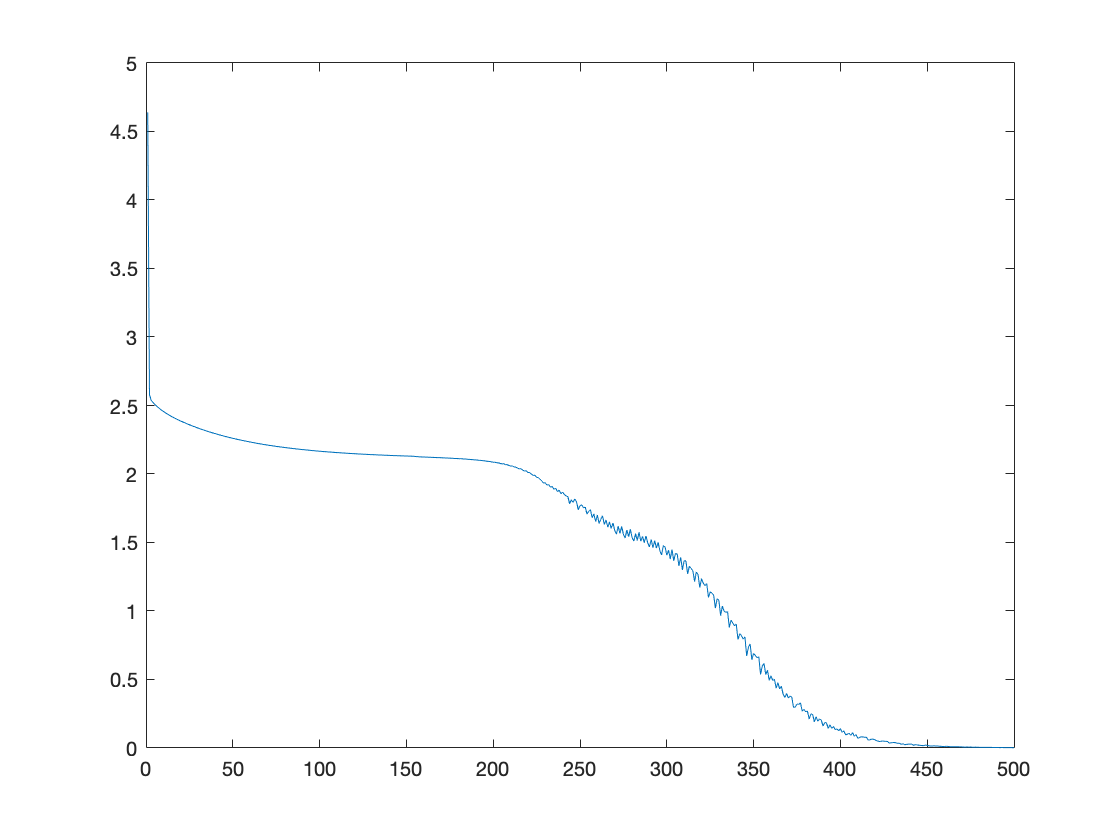

% graphing the inaccurcies
figure(1)
plot(inaccuracies)

Final weights and biases

w1

w1 =     0.7254    0.7147
    0.9369    0.7950


w2

w2 =     0.8759    0.4090
         0         0


bias_1

bias_1 =     0.6715    0.7925


bias_2

bias_2 =     0.7172         0


Testing the Model

% stuff for testing the model
for j = 1:num_data_points

    test_output_0 = x(j, [1 2]);

    [test_output_1, ~, ~, ~] = array(w1, bias_1, test_output_0, delta_1, lr, model, 0, 2);

    [test_output_2, ~, ~, ~] = array(w2, bias_2, test_output_1, delta_2, lr, model, 0, 2);

    disp("Data")
    test_output_0
    disp("Prediction")
    test_output_2(1)
end

Data


test_output_0 =      0     0


Prediction


ans = 1.6295

Data


test_output_0 =      0     1


Prediction


ans = 2.5807

Data


test_output_0 =      1     0


Prediction


ans = 2.6481

Data


test_output_0 =      1     1


Prediction


ans = 3.5993